# EE4530 Applied Convex Optimization mini-Project - SVM

## Clear all

clear all;
clc;
close all;

## 1. Data Load

load("linear_svm.mat");

### Data Exploration

Take a look at the distribution of the data

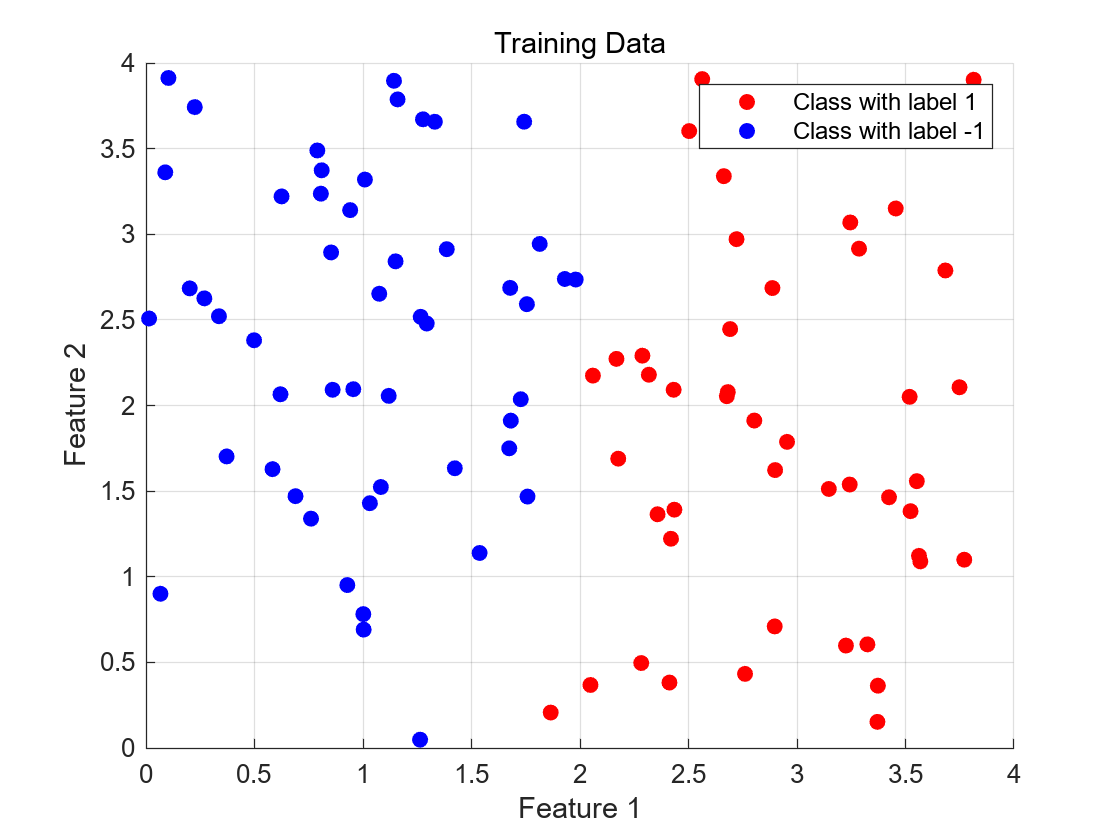

% plot the training data
figure;

% plot data with label = 1
scatter(X_train(labels_train == 1, 1), X_train(labels_train == 1, 2), 'ro', 'filled');
hold on;

% plot data with label = -1
scatter(X_train(labels_train == -1, 1), X_train(labels_train == -1, 2), 'bo', 'filled');

title('Training Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
% axis padded;
hold off;

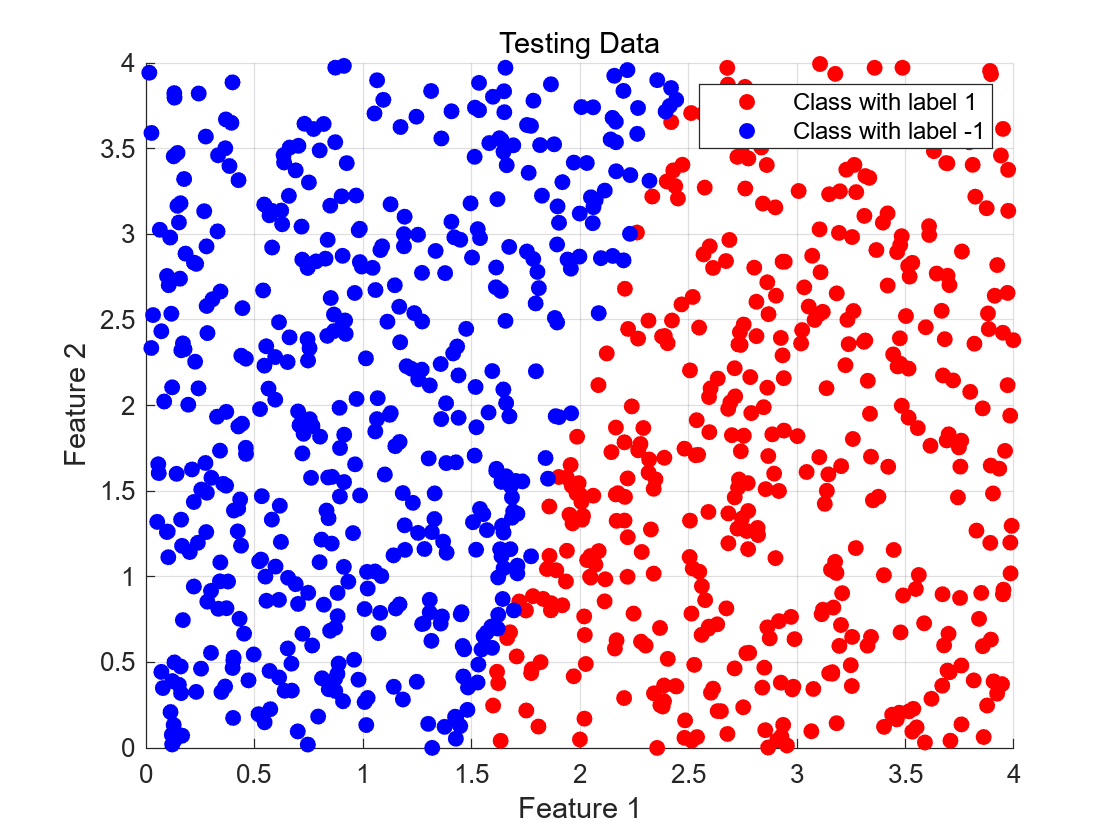

% plot the testing data
figure;

% plot data with label=1
scatter(X_test(labels_test == 1, 1), X_test(labels_test == 1, 2), 'ro', 'filled');
hold on;

% plot data with label=-1
scatter(X_test(labels_test == -1, 1), X_test(labels_test == -1, 2), 'bo', 'filled');

title('Testing Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
hold off;

## 1.Task 1

硬约束: svm最优化目标为最大化决策边界, 转化为下面的公式


$$\min_{\vec{w}} f(\vec{w})=\frac{||\vec{w}||^2}{2} \\
\text{s.t.}  \ g_i(\vec{w}, b) = y_i \cdot(\vec{w}\cdot \vec{x_i} + b) \geq 1

$$


[N_train, n] = size(X_train);
[N_test, n] = size(X_test);
C = 2;

tic;        % 运算时长
% Convex计算
cvx_begin
    variables w(n) b delta(N_train);
    % 目标
    minimize(0.5 * w' * w + C*sum(delta));

    % 约束条件
    subject to
        for i = 1:N_train
            labels_train(i) * (X_train(i, :) * w + b) >= 1 - delta(i);
            delta(i) >= 0;
        end
cvx_end

 
Calling SDPT3 4.0: 205 variables, 101 equality constraints
------------------------------------------------------------

 num. of constraints = 101
 dim. of socp   var  =  4,   num. of socp blk  =  1
 dim. of linear var  = 200
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.1e-01|1.3e+01|1.2e+05| 5.657905e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.714|2.4e-06|3.9e+00|5.3e+04| 7.499578e+03 -2.866485e+01| 0:0:00| chol  1  1 
 2|0.602|0.293|4.2e-06|2.8e+00|4.4e+04| 7.836137e+03 -7.306347e+01| 0:0:00| chol  1  1 
 3|1.000|0.160|9.7e-06|2.3e+00|4.8e+04| 9.716

time = toc;

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (3.745959, -0.653832)'
Optimal b: -6.047234
Running time: 1.338701

y_pre = svm_predict(w, b, X_test);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.975556

## 2. Task 2

% data preprocessing
X_train_normalized = normalize(normalize(X_train), "range");
X_test_normalized = normalize(normalize(X_test), "range");

% 超参数
lambda = 0.01;
t = 0.01;
num_iters = 10000;


## Method 1: SGD

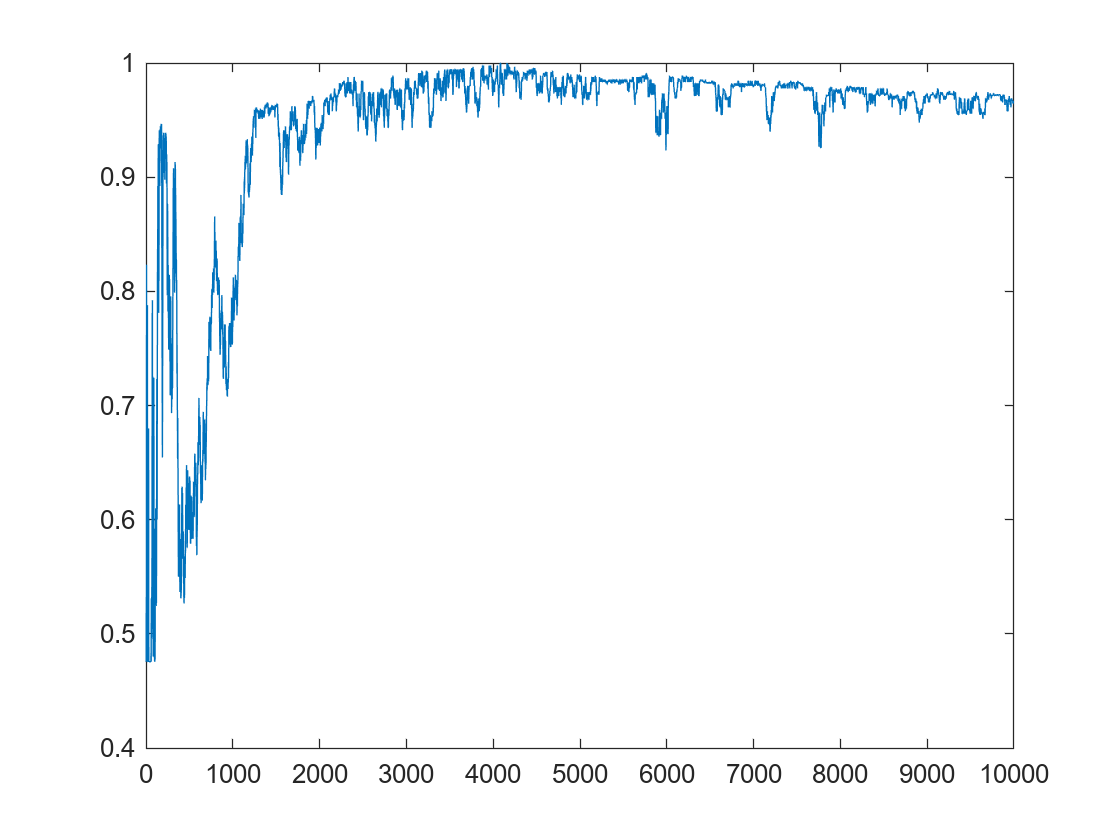


% 训练 SVM
tic;
[w, b, acc_gd] = svm_gd(X_train_normalized, labels_train, X_test_normalized, labels_test, lambda, t, num_iters);
time = toc;
figure(1);
plot(acc_gd);

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (4.465209, -0.727293)'
Optimal b: -1.910000
Running time: 0.051795

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.966667

## Method 2: BLS

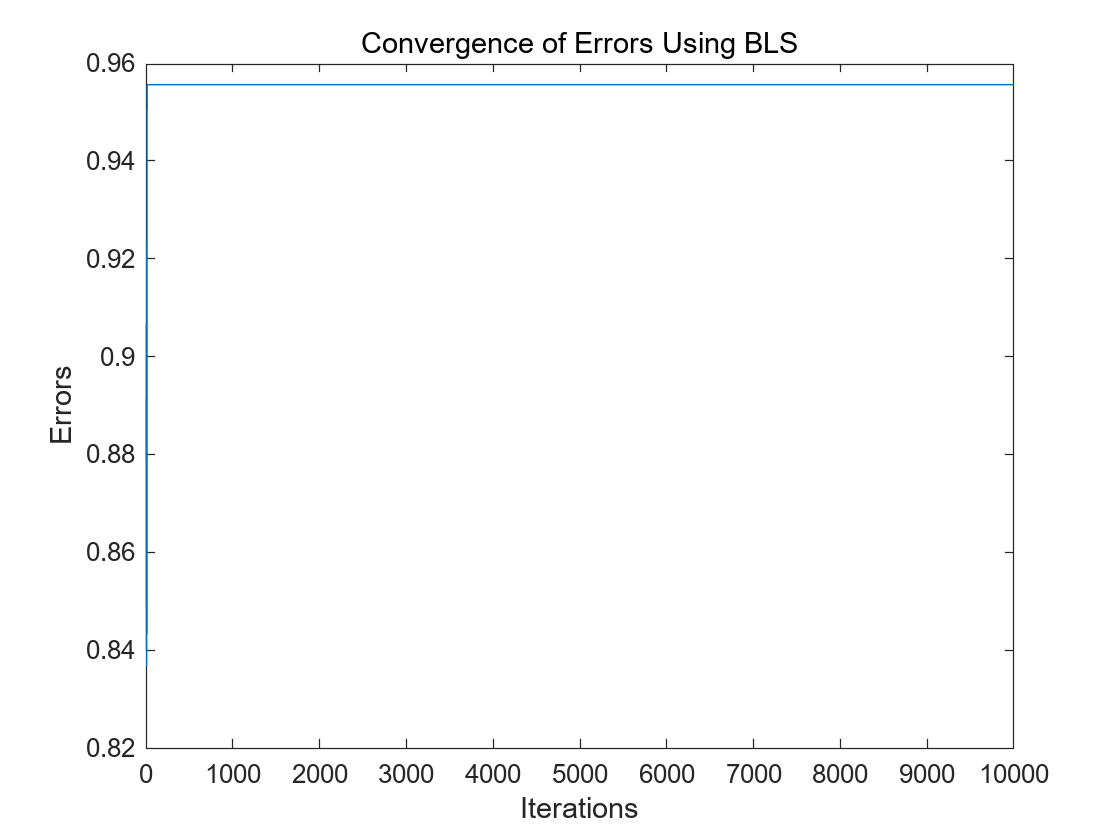


% 超参数
% num_iters = 1000;
alpha = 0.25;
beta = 0.5;
t0 = 0.01;

% 训练 SVM
tic;
[w, b, iter, w_list, b_list, acc_bls] = svm_bls(X_train_normalized, labels_train, X_test_normalized, labels_test, lambda, num_iters, alpha, beta, t0);
figure(2);
plot(acc_bls);
title("Convergence of Errors Using BLS");
xlabel("Iterations");
ylabel("Errors");

time_bls = toc;

% 显示结果
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nNumber of iteration: %d", ...
    w(1), w(2), b, time_bls, iter);

Optimal w: (5.170825, -0.585432)'
Optimal b: -2.328125
Running time: 0.041289
Number of iteration: 13

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy); 

Test Acc: 0.955556

## Opt: Lag

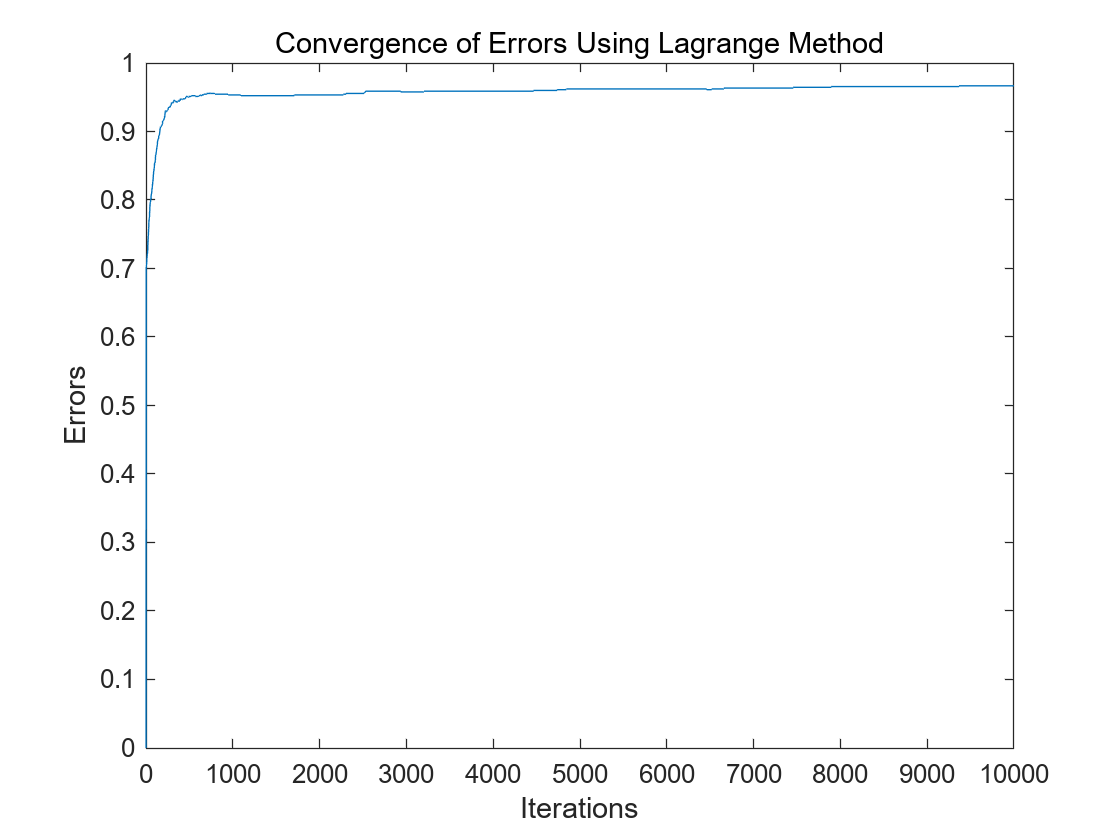


tic;
lr = 0.01;
[w, b, alpha, w_list_lg, b_list_lg, acc_lg] = svm_lag(X_train_normalized, labels_train, X_test_normalized, labels_test, lr, num_iters);
time_lag = toc;
y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
figure(3);
plot(acc_lg);
title("Convergence of Errors Using Lagrange Method");
xlabel("Iterations");
ylabel("Errors");

fprintf("Test Acc: %f", accuracy); 

Test Acc: 0.966667

fprintf("Training Time: %f", time_lag);

Training Time: 0.089037

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (3.150060, -1.048017)'
Optimal b: -1.032888
Running time: 0.051795

## Dual


tic;
[w, b, alpha, acc_dual] = svm_dual_gd(X_train_normalized, labels_train, X_test_normalized, labels_test, 0.001, num_iters);
time_dual_gd = toc;
y_pre = svm_predict(w, b, X_test_normalized);
test_dual_accuracy = svm_report(labels_test, y_pre);
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time_dual_gd);

Optimal w: (1.315150, -0.278863)'
Optimal b: -0.541599
Running time: 0.510715

fprintf("svm dual acc: %f", test_dual_accuracy);

svm dual acc: 0.972222

fprintf("svm dual time: %f", time_dual_gd);

svm dual time: 0.510715

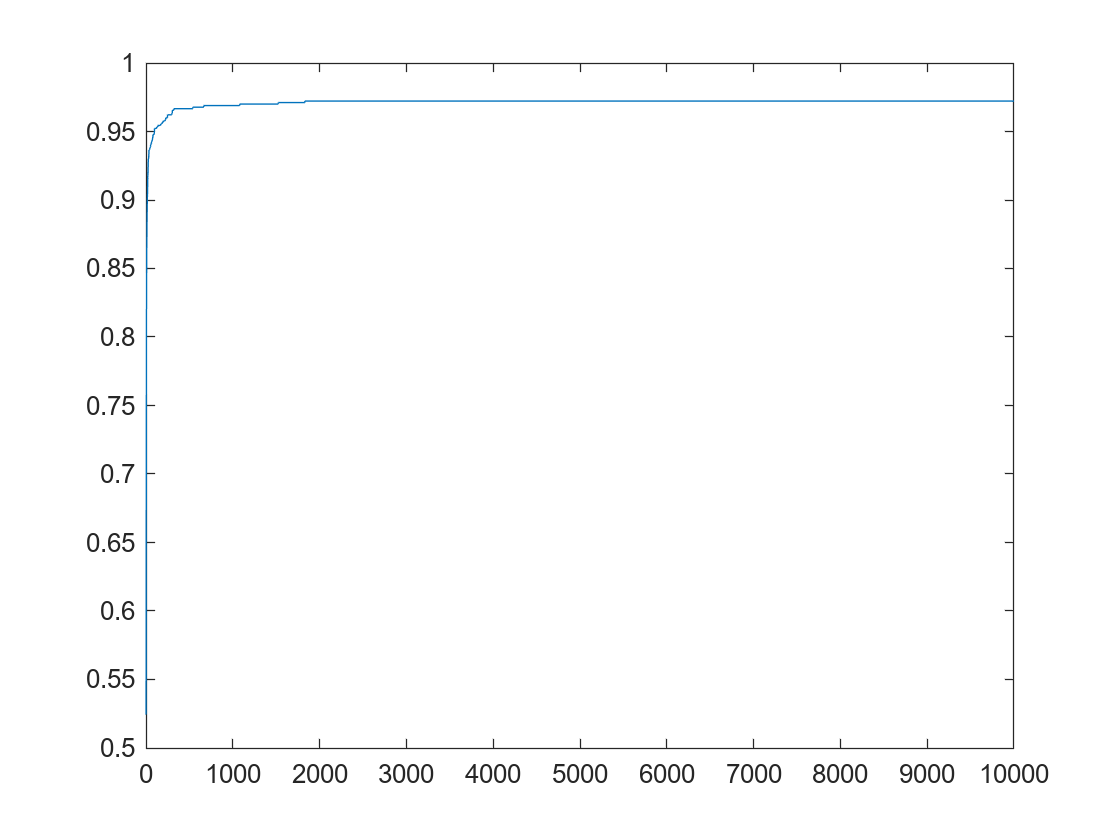

plot(acc_dual);

## Comparison

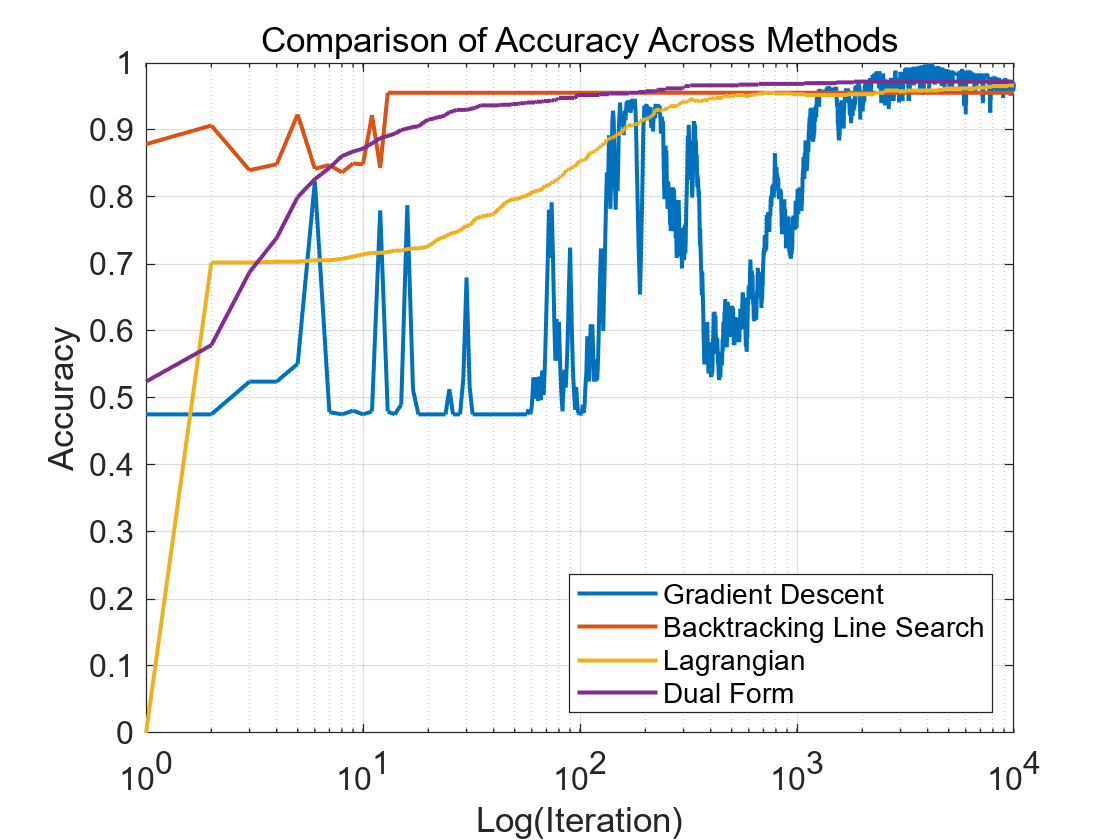

% 假设 acc_gd, acc_bls, acc_lg, acc_dual 是四种方法的准确率记录向量
% 横坐标为迭代次数
num_iters = length(acc_gd);
x = 1:num_iters; % 迭代次数

% 绘制准确率曲线
figure;
semilogx(x, acc_gd, 'LineWidth', 1.5); hold on; % 使用对数横坐标
semilogx(x, acc_bls, 'LineWidth', 1.5);
semilogx(x, acc_lg, 'LineWidth', 1.5);
semilogx(x, acc_dual, 'LineWidth', 1.5);

% 图例和轴标签
legend({'Gradient Descent', 'Backtracking Line Search', 'Lagrangian', 'Dual Form'}, ...
    'Location', 'southeast');
xlabel('Log(Iteration)'); % 对数横坐标
ylabel('Accuracy');
title('Comparison of Accuracy Across Methods');
grid on;

% 优化视觉效果
set(gca, 'FontSize', 12); % 设置字体大小
hold off;